% Beauchemin model with contact inhibition to simulate cell migration
% and cell clustering, respectively
% Models are taken from 
% "Analytical results on the Beauchemin model of lymphocyte migration"
% and implimented to the best of my ability and understanding 
% Due to the disreteness of the following methods, t-pause is consdiered
% once every five time steps, and t-free is considered for the other four.
% This is because of the suggested optimal values of t-pause = 0.5min and
% t-free = 2min. To maintain this ratio, this is how the time steps will be
% considered. Each point ("cell") will have five properties: 3 coordinates
% in the volume, an orientation angle, and a velocity. Different models are
% explored here.
% In addition to the models, a feature added is a clustering radius. This
% is a radius in which if cells become close enough to one another, they
% stick together and stop moving. This simulates contact inhibition
% locomotion cessation of motion. 

% Note: Spherical coordinates are used often in this code. Naming
% coventions are as follows: theta = [0, pi], phi = [0, 2pi], 
% x = v * sin(theta) * cos(phi)
% y = v * sin(theta) * sin(phi)
% z = v * cos(theta) 
clear

%%%%%%%%%%%%%%%%%%%%
% Global Variables %
%%%%%%%%%%%%%%%%%%%%
num_cells = 20;
range = 10;
r = 20;
t = 10;
v = 1;
n = 4;
T = 80;
p = 0.99;

%%%%%%%%%%%%%%%%%%%%%

[x0, y0, z0] = getUniformDist(100, 20);
tic
[x1, y1, z1] = topotaxisCess(x0, y0, z0, v, r, t, T, n, p);
[x2, y2, z2] = topotaxisCess(x1, y1, z1, v, r, t, T, n, p);
[x3, y3, z3] = topotaxisCess(x2, y2, z2, v, r, t, T, n, p);
disp('1');

1


disp(mean(x1))

    8.9445



disp(mean(y1));

    8.9731



disp(mean(z1));

    9.9464



disp('2');

2


disp(mean(x2))

    7.8796



disp(mean(y2));

    7.9114



disp(mean(z2));

    9.7535



disp('3');

3


disp(mean(x3))

    6.8711



disp(mean(y3));

    6.8660



disp(mean(z3));

    9.3664



toc

Elapsed time is 16.830473 seconds.


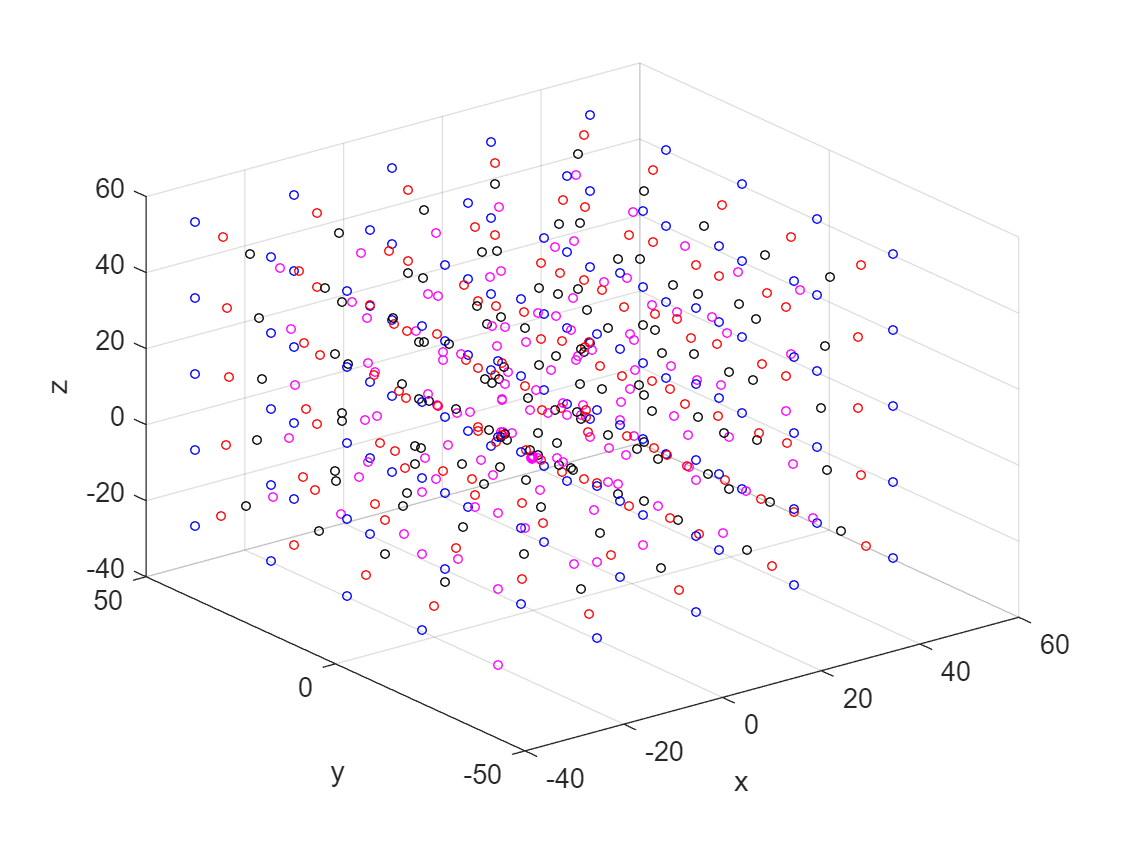



scatter3(x0, y0, z0, 10, 'b');
hold on
scatter3(x1, y1, z1, 10, 'r');
hold on
scatter3(x2, y2, z2, 10, 'k');
hold on 
scatter3(x3, y3, z3, 10, 'm');
hold off
xlabel('x');
ylabel('y');
zlabel('z');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% INITIAL DISTRIBUTION FUCNTIONS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, y, z] = getRandomDist(num_cells, range)
    % obtains uniform distribution in the cube defined by the range value.
    % The num_cells is the total size of the array returned
    points = (rand(3, num_cells)- 0.5).*range;
    x = points(1, :);
    y = points(2, :);
    z = points(3, :);
end

function [x, y, z] = getSphericalDist(num_particles, radius)
    % Uniformly random distribution within a sphere of given radius
    x = zeros(1, num_particles);
    y = zeros(1, num_particles);
    z = zeros(1, num_particles);
    for i = 1:num_particles
        phi = 2*pi*rand;
        theta = acos(1 - 2*rand);
        randR = (rand)^(1/3) * radius;
        x(i) = sin(theta) * cos(phi) * randR;
        y(i) = sin(theta) * sin(phi) * randR;
        z(i) = cos(theta) * randR;
    end
end

function [x, y, z] = getUniformDist(range, density)
    % uniform distriubtion, no randomness, with constant density
    % density is defined as unit of volume per particle
    num_particles = range / density;
    x = zeros(1, num_particles^3);
    y = zeros(1, num_particles^3);
    z = zeros(1, num_particles^3);
    counter = 1;
    for xi = 1:num_particles
        for yi = 1:num_particles
            for zi = 1:num_particles
                x(counter) = xi * density;
                y(counter) = yi * density;
                z(counter) = zi * density;
                counter = counter + 1;
            end
        end
    end
    % centering
    x = x - range / 2;
    y = y - range / 2;
    z = z - range / 2;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% FUNCTIONS FOR CELL MIGRATION AND CLUSTERING SIMULATION %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [xn, yn, zn] = beauchemin(x, y, z, v, r, t, T, n)
    % Simulating beauchemin cell migration with CIL cessation of motion.
    % x, y, z are intial seeding of points
    % r - clustering radius
    % v - velocity, constant for this model
    % t - how many divisions occur within one time step, would be a
    % continuous system if t = inifity
    % T - total number of time steps
    % n - relative time length of t-free to t-pause, for example, if n = 4,
    % this is in accordance with the experimental values. If n=5, this
    % means t-free is 5 times longer than t-pause, etc. 
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase, recalculate angles
            angles = uniformAngles(size(x, 2));
        else
            % free phase, initiate movement
            [xn, yn, zn] = unbiasedWalkCess(xn, yn, zn, v, r, angles, t);
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% SIMPLE PHENONILOGICAL MODELS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [xn, yn, zn] = simplePhenomCess(x, y, z, v, r, t, T, n, p)
    % This is a simple model that adds bias to the cell migration. Instead
    % of the cells reamining in the same spot during the pause phase, the
    % cells drift at a rate v*p towards the center of the volume. 
    % CIL implemented here is cessation of motion
    % range - range of the volume
    % p - [0, 1], 0-unbiased, 1-maximum bias
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase, recalculate angles
            angles = uniformAngles(size(x, 2));
            % drift every cell towards the center
            [xn, yn, zn] = drift(xn, yn, zn, v*p);
        else
            % free phase, initiate movement
            [xn, yn, zn] = unbiasedWalkCess(xn, yn, zn, v, r, angles, t);
        end
    end
end

function [xn, yn, zn] = simplePhenomCC(x, y, z, v, r, t, T, n, p)
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase, recalculate angles
            angles = uniformAngles(size(x, 2));
            % drift every cell towards the center
            [xn, yn, zn] = drift(xn, yn, zn, v*p);
        else
            % free phase, initiate movement
            [xn, yn, zn] = unbiasedWalkCC(xn, yn, zn, v, r, angles, t);
        end
    end
end

function [xn, yn, zn] = simplePhenomRepol(x, y, z, v, r, t, T, n, p)
    % simple phenomilogical model with repolarization upon contact 
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase, recalculate angles
            angles = uniformAngles(size(x, 2));
            % drift every cell towards the center
            [xn, yn, zn] = drift(xn, yn, zn, v*p);
        else
            % free phase, initiate movement
            [xn, yn, zn] = unbiasedWalkRepol(xn, yn, zn, v, r, angles, t);
        end
    end
end

%%%%%%%%%%%%%%%%%%%%
% ORTHOAXIS MODELS %
%%%%%%%%%%%%%%%%%%%%

function [xn, yn, zn] = orthoaxisCess(x, y, z, v, r, t, T, n, p)
    % orthoaxis bias influences the direction of cell migration by
    % modulating the velocity relative to the direction. If the cell moves
    % in the intended direction, the velocity is faster. If it moves against
    % the intended direction, it moves slower. Perpendicular to the
    % direction, unaffected. 
    % CIL implimented here is cessation of motion
    % p - [0,1] amount of bias towards the inteded direction. Here, the
    % inteded direction is towards the center. 0 unbiased, 1 maximum bias
    % v' = v * (1 + p * <b, d>), b is the untit vector towards the center, d is
    % the unit vector desribed by the direction of the cell
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase, recalculate angles
            angles = uniformAngles(size(x, 2));
        else
            % free phase, calculate v' for points and move
            [xn, yn, zn] = orthoWalk(xn, yn, zn, v, r, angles, t, p);
        end
    end
end

function [xn, yn, zn] = orthoaxisCC(x, y, z, v, r, t, T, n, p)
    % same algorithm as above with the difference being contact clumping
    % CIL. This assigns the same angle of motion to a clump of cells during
    % the pause phase. If a cell runs into a clump of cells, it changes its
    % angle to the angle of the clump. 
    xn = x;
    yn = y;
    zn = z;
    angles = clumpedAngles(contactClumping(x, y, z, r));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase
            % reassign angles by clumping
            angles = clumpedAngles(contactClumping(xn, yn, zn, r));
        else 
            % free phase
            % calculate v' and check if newly clumped, change angles
            [xn, yn, zn] = orthoCCWalk(xn, yn, zn, v, r, angles, t, p);
        end
    end
end

function [xn, yn, zn] = orthoaxisRepol(x, y, z, v, r, t, T, n, p)
    % repolarization 
    xn = x;
    yn = y;
    zn = z;
    angles = uniformAngles(size(x, 2));
    for i = 1:T
        if(mod(i, n) == 1)
            % pause phase
            % reassign angles by clumping
            angles = uniformAngles(size(x, 2));
        else 
            % free phase
            % calculate v' and check if newly clumped, change angles
            [xn, yn, zn] = orthoRepolWalk(xn, yn, zn, v, r, angles, t, p);
        end
    end
end

%%%%%%%%%%%%%%%%%%%%
% TOPOTAXIS MODELS %
%%%%%%%%%%%%%%%%%%%%

function [xn, yn, zn] = topotaxisCess(x, y, z, v, r, t, T, n, p)
    % This biased migration operates by choosing the random angles from a
    % beta distribution that has a mean value towards the origin. This
    % tends the cells towards the center of space
    xn = x;
    yn = y;
    zn = z;
    angles = biasedAngles(x, y, z, p);
    for s = 1:T
        if(mod(s, n) == 1)
            % pause phase
            angles = biasedAngles(xn, yn, zn, p);
        else 
            % free phase, follow unbiasedWalkCess witht the biased angles
            [xn, yn, zn] = unbiasedWalkCess(xn, yn, zn, v, r, angles, t);
        end
    end
end

function [xn, yn, zn] = topotaxisCC(x, y, z, v, r, t, T, n, p)
    % topotaxis model but with contact clumping
    xn = x;
    yn = y;
    zn = z;
    angles = clumpedBiasedAngles(x, y, z, contactClumping(xn, yn, zn, r), p);
    for j = 1:T
        if(mod(j, n) == 1)
            % pause phase
            angles = clumpedBiasedAngles(x, y, z, contactClumping(xn, yn, zn, r), p);
        else
            [xn, yn, zn] = unbiasedWalkCC(xn, yn, zn, v, r, angles, t);
        end
    end
end

function [xn, yn, zn] = topotaxisRepol(x, y, z, v, r, t, T, n, p)
    % repolarization model 
    xn = x;
    yn = y;
    zn = z;
    angles = biasedAngles(x, y, z, p);
    for j = 1:T
        if(mod(j, n) == 1)
            % pause phase
            angles = biasedAngles(xn, yn, zn, p);
        end
        [xn, yn, zn] = unbiasedWalkRepol(xn, yn, zn, v, r, angles, t);
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%
% WALK HELPER FUNCTIONS %
%%%%%%%%%%%%%%%%%%%%%%%%%

function [xn, yn, zn] = unbiasedWalkCess(x, y, z, v, r, angles, t)
    % Simple, unbiased beauchemin walk with constant velocity for every 
    % point. This model has the added feature cessation of motion due to
    % CIL
    % r - clustering radius
    % v - constant velocity
    % angles - orientations of the cells, col 1 theta, col 2 phi
    % t - number of times steps to divide this movement into
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for m = 1:t
        for n = 1:size(x, 2)
            % For every point, check if it is contact inhibited. If it is, the
            % point does not move. If it is not, the point moves forward at the
            % orientation angle
            xcurr = x(n);
            ycurr = y(n);
            zcurr = z(n);
            if (isInhibited(xcurr, ycurr, zcurr, x, y, z, r))
                xn(n) = xcurr;
                yn(n) = ycurr;
                zn(n) = zcurr;
            else 
                % from polar to cartesian coordinates, v is the displacement,
                % so it is here in place of what whould normaly be radius
                xn(n) = sin(angles(2, n)) * cos(angles(1, n)) * v/t + xcurr;
                yn(n) = sin(angles(2, n)) * sin(angles(1, n)) * v/t + ycurr;
                zn(n) = cos(angles(2, n)) * v/t + zcurr;
            end
        end
    end
end

function [xn, yn, zn] = unbiasedWalkCC(x, y, z, v, r, angles, t)
    % unbiased walk with contact clumping 
    xn = x;
    yn = y;
    zn = z;
    for l = 1:t
        % for each time step, check the clumps, and reassign the angles
        updatedClumps = contactClumping(xn, yn, zn, r);
        updatedAngles = reassignAngles(updatedClumps, angles);
        for h = 1:size(x, 2)
            % for each point, move the cell by v / t
            xn(h) = sin(updatedAngles(2, h)) * cos(updatedAngles(1, h)) * v/t + xn(h);
            yn(h) = sin(updatedAngles(2, h)) * sin(updatedAngles(1, h)) * v/t + yn(h);
            zn(h) = cos(updatedAngles(2, h)) * v/t + zn(h);
        end
    end
end

function [xn, yn, zn] = unbiasedWalkRepol(x, y, z, v, r, angles, t)
   xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for m = 1:t
        for n = 1:size(x, 2)
            % For every point, check if it is inhibited. If it is, the
            % particle reverses its angle. Regardless, the point moves
            % forward
            xcurr = x(n);
            ycurr = y(n);
            zcurr = z(n);
            if (isInhibited(xcurr, ycurr, zcurr, x, y, z, r))
                angles(1, n) = 2*pi - angles(1, n);
                angles(2, n) = pi - angles(2, n);
            end 
            % from polar to cartesian coordinates, v is the displacement,
            % so it is here in place of what whould normaly be radius
            xn(n) = sin(angles(2, n)) * cos(angles(1, n)) * v/t + xcurr;
            yn(n) = sin(angles(2, n)) * sin(angles(1, n)) * v/t + ycurr;
            zn(n) = cos(angles(2, n)) * v/t + zcurr;
        end
    end
end

function [xn, yn, zn] = orthoCCWalk(x, y, z, v, r, angles, t, p)
    % instead of stopping a cell if it is inhibited, recaclualte the
    % clumps and change the angle to the angle of the clumps
    xn = x;
    yn = y;
    zn = z;
    for o = 1:t
        % for each time step, check the clumps, and reassign the angles
        updatedClumps = contactClumping(xn, yn, zn, r);
        updatedAngles = reassignAngles(updatedClumps, angles);
        for q = 1:size(x, 2)
            % for each cell, move the cell by the calculated v'
            % this differs from orthoWalk becuase we do not need to check
            % if a cell is inhibited, since it moves with its clump
            xcurr = x(q);
            ycurr = y(q);
            zcurr = z(q);
            % first calculate v' based on direction of motion
            phi = updatedAngles(1, q);
            theta = updatedAngles(2, q);
            rad = sqrt(xcurr^2 + ycurr^2 + zcurr^2);
            % converting angles into unit vector
            dx = sin(theta)*cos(phi);
            dy = sin(theta)*sin(phi);
            dz = cos(theta);
            % negate to flip the vector to point towards the origin and
            % divide by rad to make it a unit vector
            bx = -xcurr / rad;
            by = -ycurr / rad;
            bz = -zcurr / rad;
            % dot product and generation of v'
            % v' = v * (1 + p * <b, d>)
            vprime = v * (1 + p*(dx*bx + dy+by + dz*bz));
            % use new velocity
            % from polar to cartesian coordinates, v' is the displacement,
            xn(q) = dx * vprime/t + xcurr;
            yn(q) = dy * vprime/t + ycurr;
            zn(q) = dz * vprime/t + zcurr;
        end
    end
end

function [xn, yn, zn] = orthoWalk(x, y, z, v, r, angles, t, p)
    xn = x;
    yn = y;
    zn = z;
    for a = 1:t
        for b = 1:size(x, 2)
            xcurr = x(b);
            ycurr = y(b);
            zcurr = z(b);
            if (isInhibited(xcurr, ycurr, zcurr, x, y, z, r))
                xn(b) = xcurr;
                yn(b) = ycurr;
                zn(b) = zcurr;
            else
                % first calculate v' based on direction of motion
                phi = angles(1, b);
                theta = angles(2, b);
                rad = sqrt(xcurr^2 + ycurr^2 + zcurr^2);
                % converting angles into unit vector
                dx = sin(theta)*cos(phi);
                dy = sin(theta)*sin(phi);
                dz = cos(theta);
                % negate to flip the vector to point towards the origin and
                % divide by rad to make it a unit vector
                bx = -xcurr / rad;
                by = -ycurr / rad;
                bz = -zcurr / rad;
                % dot product and generation of v'
                % v' = v * (1 + p * <b, d>)
                vprime = v * (1 + p*(dx*bx + dy+by + dz*bz));
                % use new velocity
                % from polar to cartesian coordinates, v' is the displacement,
                xn(b) = dx * vprime/t + xcurr;
                yn(b) = dy * vprime/t + ycurr;
                zn(b) = dz * vprime/t + zcurr;
            end
        end
    end
end

function [xn, yn, zn] = orthoRepolWalk(x, y, z, v, r, angles, t, p)
    xn = x;
    yn = y;
    zn = z;
    for a = 1:t
        for b = 1:size(x, 2)
            xcurr = x(b);
            ycurr = y(b);
            zcurr = z(b);
            if (isInhibited(xcurr, ycurr, zcurr, x, y, z, r))
                angles(1, b) = 2*pi - angles(1, b);
                angles(2, b) = pi - angles(2, b);
            end
            % first calculate v' based on direction of motion
            phi = angles(1, b);
            theta = angles(2, b);
            rad = sqrt(xcurr^2 + ycurr^2 + zcurr^2);
            % converting angles into unit vector
            dx = sin(theta)*cos(phi);
            dy = sin(theta)*sin(phi);
            dz = cos(theta);
            % negate to flip the vector to point towards the origin and
            % divide by rad to make it a unit vector
            bx = -xcurr / rad;
            by = -ycurr / rad;
            bz = -zcurr / rad;
            % dot product and generation of v'
            % v' = v * (1 + p * <b, d>)
            vprime = v * (1 + p*(dx*bx + dy+by + dz*bz));
            % use new velocity
            % from polar to cartesian coordinates, v' is the displacement,
            xn(b) = dx * vprime/t + xcurr;
            yn(b) = dy * vprime/t + ycurr;
            zn(b) = dz * vprime/t + zcurr;
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%
% ANGLE HELPER FUNCTIONS %
%%%%%%%%%%%%%%%%%%%%%%%%%%

function angles = uniformAngles(n)
    % generates n uniformly distriubted angles. Essentialy, a uniform
    % distribution on a unit sphere. col 1 - phi, col 2 - theta 
    angles = zeros(2, n);
    for d = 1:n
        angles(1, d) = 2*pi*rand;
        angles(2, d) = acos(1 - 2*rand);
    end
end

function angles = biasedAngles(x, y, z, p)
    % Produces random angles phi and theta for each cell in the space that
    % are skewed towards the origin. The angles are drawn from a beta
    % distriubtion with mean values for phi and theta that are equal to the
    % values that point to the origin.
    % p - [0, 1) variance of the distribution, 0 for unbiased, 0.999... for
    % maximum bias. p ~= 1 becuase this leads to a divide by zero error
    angles = zeros(2, size(x, 2));
    a = 1 / (1-p);
    for i = 1:size(x, 2)
        % for each cell, find the angles towards the center
        xcurr = x(i);
        ycurr = y(i);
        zcurr = z(i);
        % unit vector towards the center
        % negate values to flip the vector to face inwards
        phicurr = 0;
        thetacurr = 0;
        if (zcurr ~= 0)
            thetacurr = acos(-zcurr / sqrt(xcurr^2 + ycurr^2 + zcurr^2));
        end
        if (xcurr > 0)
            phicurr = atan(-ycurr / xcurr);
        end
        if (xcurr < 0 && ycurr >= 0)
            phicurr = atan(-ycurr / xcurr) + pi;
        end
        if(xcurr < 0 && ycurr < 0)
            phicurr = atan(-ycurr / xcurr ) - pi;
        end
        if(xcurr == 0 && ycurr > 0)
            phicurr = pi / 2;
        end
        if(xcurr == 0 && ycurr < 0)
            phicurr = -pi / 2;
        end
        % get random phi and theta from beta distribution centered at
        % angles
        angles(1, i) = ((betarnd(a, a)-0.5)* 2 * pi - phicurr);
        angles(2, i) = (acos(1 - 2*(betarnd(a, a))) * pi + pi/2 - thetacurr);
    end
 
end

function angles = clumpedAngles(clumps)
    % Using the function contactClumping below to produce the same random
    % angles for each clump. This makes it so for every cell in a clump,
    % all of the cells move in the same direction. This is supposed to
    % simulate CIL addhesion between cells
    angles = zeros(2, size(clumps, 2));
    for e = 1:size(clumps, 2)
        % for each clump, check that the first value is not zero. If it is,
        % then it is an empty clump
        if(clumps(1, e) ~= 0)
            % generate the random angles for the whole clump
            phi = 2*pi*rand;
            theta = acos(1 - 2*rand);
            for f = 1:size(clumps, 1)
                % for each non-zero value in the clump, assign the angles
                % to the index given by clumps
                if(clumps(f, e) ~= 0)
                    currindex = clumps(f, e);
                    angles(1, currindex) = phi;
                    angles(2, currindex) = theta;
                end
            end
        end
    end
end

function angles = clumpedBiasedAngles(x, y, z, clumps, p)
    % Using the function contactClumping below to produce the same random
    % angles for each clump. This makes it so for every cell in a clump,
    % all of the cells move in the same direction. This is supposed to
    % simulate CIL addhesion between cells
    angles = zeros(2, size(clumps, 2));
    a = 1 / (1-p);
    [xcenters, ycenters, zcenters] = clumpGeoCenters(x, y, z, clumps);
    for e = 1:size(clumps, 2)
        % for each clump, check that the first value is not zero. If it is,
        % then it is an empty clump
        % generate the biased random angles for the whole clump. The
        % angles for the clump that point to the origin are from the
        % geometric center of the clump
        if(clumps(1, e) ~= 0)
            xcent = xcenters(e);
            ycent = ycenters(e);
            zcent = zcenters(e);
            phicurr = 0;
            thetacurr = 0;
            if (zcent ~= 0)
                thetacurr = acos(-zcent / sqrt(xcent^2 + ycent^2 + zcent^2));
            end
            if (xcent > 0)
                phicurr = atan(-ycent / xcent);
            end
            if (xcent < 0 && ycent >= 0)
                phicurr = atan(-ycent / xcent) + pi;
            end
            if(xcent < 0 && ycent < 0)
                phicurr = atan(-ycent / xcent ) - pi;
            end
            if(xcent == 0 && ycent > 0)
                phicurr = pi / 2;
            end
            if(xcent == 0 && ycent < 0)
                phicurr = -pi / 2;
            end
            % random angles
            phi = ((betarnd(a, a)-0.5)* 2 * pi - phicurr);
            theta = ((betarnd(a, a)-0.5) * pi - thetacurr);
            for f = 1:size(clumps, 1)
                % for each non-zero value in the clump, assign the angles
                % to the index given by clumps
                if(clumps(f, e) ~= 0)
                    currI = clumps(f, e);
                    angles(1, currI) = phi;
                    angles(2, currI) = theta;
                end
            end 
        end
    end
end

function newangles = reassignAngles(clumps, angles)
    % check that each clump has the same angle, if not, change that angle
    % to the angle given to the first item in the clump. The assignment of
    % matching the angle to the first in the clump is not arbitrary, as
    % this is the identifying cell of the clump
    newangles = zeros(size(angles));
    for h = 1:size(clumps, 2)
        % for every column, check that the first item is not zero
        if(clumps(1, h) ~= 0)
            for g = 1:size(clumps, 1)
                % for every row, check that the value is not zero and
                % assign the angle to the same as the first value in the
                % column
                currPhi = angles(1, h);
                currTheta = angles(2, h);
                if(clumps(g, h) ~= 0)
                    % if it is not zero, get the index and change that
                    % index in angles to be the current angles
                    currI = clumps(g, h);
                    newangles(1, currI) = currPhi;
                    newangles(2, currI) = currTheta;
                end
            end
        end
    end
end

function newangles = repolarization(x, y, z, angles, r)
    % If any two cells are within the collision radius, reverse their
    % angles. This simulates repolarization of the cell at an instantanious
    % rate. In the unlikely event that a cell approaches more than one cell
    % and colides with them at the same time, the cell will turn away from only 
    % the closest cell
    newangles = angles;
    for w = 1:size(x, 2)
        [dist, ~] = distToPoint(x(w), y(w), z(w), x, y, z);
        if(dist(1) <= r)
            % if the current cell has collided with another cell, reverse
            % the angle
            angles(1, w) = 2*pi - angles(1, w);
            angles(2, w) = pi - angles(2, w);
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CONTACT AND DRIFT FUNCTIONS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function clumps = contactClumping(x, y, z, r)
    % This is a model for CIL which has the following rules: 
    % If a cell is within radius r of another cell, they get stuck
    % together. Cells can only be a part of one clump and every cell must
    % be in a clump. The maximum number of clumps is the number of cells
    % Go through every cell. Put the current cell in a new clump. Add all
    % cells that are within or equal to radius r to that clump. Then, combine clumps
    % that have any values in common, eliminate repitions and zeros 
    % (because no indexes have 0), and return
 
    clumps = zeros(size(x, 2), size(x, 2));
    % id set for the points
    for i = 1:size(x, 2)
        xcurr = x(i);
        ycurr = y(i);
        zcurr = z(i);
        % for each point, get the distances to every other point
        [currdists, currindexes] = sort(sqrt((xcurr-x).^2 + (ycurr - y).^2 + (zcurr - z).^2));
        currclump = zeros(1, 1);
        % for every point with distance less than or equal to r, add to the
        % current clump, including current clump (that is why the distance
        % zero is not removed from currdists
        for k = 1:size(currdists, 2)
            curRad = currdists(k);
            % since the list is sorted, if the curRad is greater than r, no
            % other distances will be less than r
            if curRad > r
                break;
            end
            currclump(k) = currindexes(k);
        end
        % adding current clump to list of clumps;
        % if the current point is a part of a clump already, add all the
        % other points to that list an emilinate duplicates. If not, we
        % have found a lone point and should create a new clump
        if(ismember(clumps, currclump(1)))
            [~, col] = find(currclump(1));
            clumps(:, col) = unique([clumps(:, col); currclump]);
        end
        if(~ismember(clumps, currclump(1)))
            clumps(1:size(currclump, 2), currclump(1)) = currclump;
        end
    end
    % remove zeros
end

function [xn, yn, zn] = drift(x, y, z, a)
    % drift the cells towards the center of the volume at a rate of a
    % a - drift velocity
    xn = zeros(size(x));
    yn = zeros(size(y));
    zn = zeros(size(z));
    for c = 1: size(x, 2)
        % for every cell, calculate the spherical angles for that cell and
        % the radius, decrease the radius by a and then shift to the center
        % of the volume
        xcurr = x(c);
        ycurr = y(c);
        zcurr = z(c);
        % getting the current radius
        currR = sqrt(xcurr^2 + ycurr^2 + zcurr^2);
        % shrinking the radius to simulate the drift
        if (currR > a)
            % only drift the cell in if it is farther away than the drift
            % velocity 
            r_new = currR - a;
            % generating the new coordinates
            xn(c) = xcurr * r_new / currR;
            yn(c) = ycurr * r_new / currR;
            zn(c) = zcurr * r_new / currR;
        else
            % otherwise, leave it alone 
            xn(c) = xcurr;
            yn(c) = ycurr;
            zn(c) = zcurr;
        end
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% GENERAL HELPER FUNCTIONS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [distances, indexes] = distToPoint(x1, y1, z1, x, y, z)
    [distances, indexes] = sort(sqrt(((x1-x).^2) + ((y1-y).^2) + ((z1-z).^2)));
    % Remove distance 0
    if(distances(1) == 0)
        distances = distances(2:end);
        indexes = indexes(2:end);
    end
end

function [xlst, ylst, zlst] = clumpGeoCenters(x, y, z, clumps)
    % helper function for getting the geometric center of each clump
    % returns a list of each center of each clump with zeros in the indexes
    % of empty clumps. This is for uniform indexing across functions. 
    xlst = zeros(size(clumps, 2));
    ylst = zeros(size(clumps, 2));
    zlst = zeros(size(clumps, 2));
    for i = 1:size(clumps, 2)
        % for each non-zero column, get the coordinates of each given
        % index. Use these coordinates to 
        if(clumps(1, i) ~= 0)
            currclump = clumps(:, i);
            currclump(currclump ==0) = [];
            xlst(i) = mean(x(currclump));
            ylst(i) = mean(y(currclump));
            zlst(i) = mean(z(currclump));
        end
    end
end

function inhibited = isInhibited(xcurr, ycurr, zcurr, x, y, z, r)
    % get the distance from the current point to every other point. If
    % there is a distances that is below r, the clustering radius, then
    % return true, else return false
    distances = zeros(size(x));
    for i = 1:size(x, 2)
        % get the distance to every point
        distances(i) = sort(sqrt((xcurr - x(i))^2 + (ycurr - y(i))^2 + (zcurr - z(i))^2));
    end
    % remove the first distance because it is zero, measuring from (xcurr,
    % ycurr, zcurr) to itself
    distances = distances(2:end);
    % if the smallest distance is greater than the clustering radius, the
    % cell is not inhibited
    if(distances(1) > r)
        inhibited = false;
    else
        inhibited = true;
    end
end